# Microarray Data Analysis

In this tutorial, we will analyze microarray data available from GEO repository hosted at NCBI ([http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)). We will rely on Matlab's Bioinformatics Toolbox for some of the file parsing and data analysis functionality.

We'll analyze the experimental data that was used in the following study: "A stromal gene signature associated with inflammatory breast cancer.", Boersma et.al., 2008. https://www.ncbi.nlm.nih.gov/pubmed/17999412

**Abstract:** The factors that determine whether a breast carcinoma will develop into inflammatory breast cancer (IBC) remain poorly understood. Recent evidence indicates that the tumor stroma influences cancer phenotypes. We tested the hypotheses that the gene expression signature of the tumor stroma is a distinctive feature of IBC. We used laser capture microdissection to obtain enriched populations of tumor epithelial cells and adjacent stromal cells from 15 patients with IBC and 35 patients with invasive, noninflammatory breast cancer (non-IBC). Their mRNA expression profiles were assessed using Affymetrix GeneChips. In addition, a previously established classifier for IBC was evaluated for the resulting data sets. The gene expression profile of the tumor stroma distinguished IBC from non-IBC, and a previously established IBC prediction signature performed better in classifying IBC using the gene expression profile of the tumor stroma than it did using the profile of the tumor epithelium. In a pathway analysis, the genes differentially expressed between IBC and non-IBC tumors clustered in distinct pathways. We identified multiple pathways related to the endoplasmic stress response that could be functionally significant in IBC. Our findings suggest that the gene expression in the tumor stroma may play a role in determining the IBC phenotype.

The data is available at https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847

## GEO data types

- GSM: An individual microarray Sample (e.g., patient, or tissue).

- GSE: A Series, representing an experimental study. A GSE contains one or more GSM entries.

- GPL: Platform data, containing information about microarray probes. Each GSM sample is associated with a GPL. E.g., to find out the gene symbols for a GSM, you would need to consult with the GPL used in that study.

## Variable names and terms

- gse: The struct returned from Matlab's geoseriesread(). Contains all the information contained in a GSE.

- d: The DataMatrix object representing the GSE data. We'll also use the prefix d to denote other DataMatrix objects, e.g., dpvals.

- m: A numerical matrix (e.g., converting d into a double).

- MAP_GSE_GPL: used to map gse probes to gpl indices, so we can get e.g., gene symbol information for a probe. IBC: inflammatory breast cancer Epithelial: the type of cells forming the breast cancer Stroma: fatty tissue (adipocytes) and fibroblasts

**Objectives:**

- Understand the gene expression using microarray 

- Differential gene expression

- Familiar with the GEO repository hosted at NCBI [http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)

- Understand the GEO data matrix structure,  GSE and GPL

- Download GEO data

- Map container containers.Map()

- Logical indexing

- Clustering and PCA analysis

- Volcano plot 

## Download GSE file and use Matlab's geoseriesread() to parse it.

https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847 See the bmes_downloadandparsegse() function for details. 

gse=bmes_downloadandparsegse5('GSE5847') % gse.header and gse.data, 22283 probes and 95 samples

Reading C:\Users\kabil\AppData\Local\Temp\GSE5847.txt ...


gse = struct with fields:
    Header: [1×1 struct]
      Data: [22283×95 bioma.data.DataMatrix]


% gse.Data is a DataMatrix object, similar to a Matlab table. In addition
% to the numerical matrix, it internally stores the row & column names.
get(gse.Data)

            Name: ''
        RowNames: {22283×1 cell}
        ColNames: {1×95 cell}
           NRows: 22283
           NCols: 95
           NDims: 2
    ElementClass: 'double'


d = gse.Data; %Let's use d for short, because we'll use this often.


**Print rownames, columnames, first 6 Probes, and first 5 samples. There is only probe information, no gene name information.  Row (probes), column (sample name), data is the fluorescent intensity. **

d.rownames

ans = 22283×1 cell array
    {'1007_s_at'  }
    {'1053_at'    }
    {'117_at'     }
    {'121_at'     }
    {'1255_g_at'  }
    {'1294_at'    }
    {'1316_at'    }
    {'1320_at'    }
    {'1405_i_at'  }
    {'1431_at'    }
    {'1438_at'    }
    {'1487_at'    }
    {'1494_f_at'  }
    {'1598_g_at'  }
    {'160020_at'  }
    {'1729_at'    }
    {'1773_at'    }
    {'177_at'     }
    {'179_at'     }
    {'1861_at'    }
    {'200000_s_at'}
    {'200001_at'  }
    {'200002_at'  }
    {'200003_s_at'}
    {'200004_at'  }
    {'200005_at'  }
    {'200006_at'  }
    {'200007_at'  }
    {'200008_s_at'}
    {'200009_at'  }

d.ColNames

ans = 1×95 cell array
    {'GSM136326'}    {'GSM136327'}    {'GSM136328'}    {'GSM136329'}    {'GSM136330'}    {'GSM136331'}    {'GSM136332'}    {'GSM136333'}    {'GSM136334'}    {'GSM136335'}    {'GSM136336'}    {'GSM136337'}    {'GSM136338'}    {'GSM136339'}    {'GSM136340'}    {'GSM136341'}    {'GSM136342'}    {'GSM136343'}    {'GSM136344'}    {'GSM136345'}    {'GSM136346'}    {'GSM136347'}    {'GSM136348'}    {'GSM136349'}    {'GSM136350'}    {'GSM136351'}    {'GSM136352'}    {'GSM136353'}    {'GSM136354'}    {'GSM136355'}    {'GSM136356'}    {'GSM136357'}    {'GSM136358'}    {'GSM136359'}    {'GSM136360'}    {'GSM136361'}    {'GSM136362'}    {'GSM136363'}    {'GSM136364'}    {'GSM136365'}    {'GSM136366'}    {'GSM136367'}    {'GSM136368'}    {'GSM136369'}    {'GSM136370'}    {'GSM136371'}    {'GSM136372'}    {'GSM136373'}    {'GSM136374'}    {'GSM136375'}    {'GSM136376'}    {'GSM136377'}    {'GSM136378'}    {'GSM136379'}    {'GSM136380'}    {'GSM136381'}    {'GSM136382'}    {'GSM

d(1:6,1:5) 

ans = 
                 GSM136326    GSM136327    GSM136328    GSM136329    GSM136330
    1007_s_at     10.45       9.3995       9.4248       9.4729       9.2788   
    1053_at      5.7195       4.8493       4.7321       4.7289       5.3264   
    117_at       5.9387       6.0833        6.448       6.1769       6.5446   
    121_at       8.0231       7.8947        8.345       8.1632       8.2338   
    1255_g_at    3.9548       3.9632       3.9641       4.0878       3.9989   
    1294_at       7.909        8.364       8.2719       8.3582          7.7   


## GSE Header information  (series and sample structures)

gse.Header

ans = struct with fields:
     Series: [1×1 struct]
    Samples: [1×1 struct]

gse.Header.Series

ans = struct with fields:
                         title: 'Tumor and stroma from breast by LCM'
                 geo_accession: 'GSE5847'
                        status: 'Public on Sep 30 2007'
               submission_date: 'Sep 15 2006'
              last_update_date: 'Mar 18 2020'
                     pubmed_id: '17999412↵19225562↵20978357'
                       summary: 'Tumor epithelium and surrounding stromal cells were isolated using laser capture microdissection of human breast cancer to examine differences in gene expression based on tissue types from inflammatory and non-inflammatory breast cancer↵Keywords: LCM'
                overall_design: 'We applied LCM to obtain samples enriched in tumor epithelium and stroma from 15 IBC and 35 non-IBC cases to study the relative contribution of each component to the IBC phenotype and to patient survival. '
                          type: 'Expression profiling by array'
                   contributor: 'Stefan,,Ambs↵Brenda,,Boersma↵Ma

gse.Header.Samples

ans = struct with fields:
                         title: {1×95 cell}
                 geo_accession: {1×95 cell}
                        status: {1×95 cell}
               submission_date: {1×95 cell}
              last_update_date: {1×95 cell}
                          type: {1×95 cell}
                 channel_count: {1×95 cell}
               source_name_ch1: {1×95 cell}
                  organism_ch1: {1×95 cell}
           characteristics_ch1: {7×95 cell}
                  molecule_ch1: {1×95 cell}
          extract_protocol_ch1: {1×95 cell}
                     label_ch1: {1×95 cell}
            label_protocol_ch1: {1×95 cell}
                     taxid_ch1: {1×95 cell}
                  hyb_protocol: {1×95 cell}
                 scan_protocol: {1×95 cell}
                   description: {1×95 cell}
               data_processing: {1×95 cell}
                   platform_id: {1×95 cell}
                  contact_name: {1×95 cell}
            contact_laboratory: {1×95 cell}
      

Get the sample title

gse.Header.Samples.title{1}

ans = 'LCM stroma sample from patient #37'

gse.Header.Samples.title{2}

ans = 'LCM stroma sample from patient #38'

gse.Header.Samples.geo_accession{1}

ans = 'GSM136326'

Print all of the available characteristics of the 20th sample

gse.Header.Samples.characteristics_ch1(:,20)

ans = 7×1 cell array
    {'diagnosis: non-IBC'     }
    {'status: Alive'          }
    {'patient_id: 8'          }
    {'race: European American'}
    {'tnm_stage: IIA'         }
    {'er_status: POS'         }
    {'tissue: Stroma'         }

Print the diagnostic information of all samples

gse.Header.Samples.characteristics_ch1(1,:)

ans = 1×95 cell array
    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis: non-IBC'}    {'diagnosis:

Print the sample sources of all samples

samplesources = gse.Header.Samples.source_name_ch1

samplesources = 1×95 cell array
    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human breast cancer stroma'}    {'human brea

GPL Platform used in this study (each manufacturer has its own array and probe sets)

gse.Header.Series.platform_id

ans = 'GPL96'

## GPL information is contained in a separate file. Download and parse it. See bmes_downloadandparsegpl(). 

gpl = bmes_downloadandparsegpl('GPL96')

gpl = struct with fields:
                 Scope: 'PLATFORM'
             Accession: 'GPL96'
                Header: [1×1 struct]
    ColumnDescriptions: {16×1 cell}
           ColumnNames: {16×1 cell}
                  Data: {22283×16 cell}

Here's the type of information we get for each microarray Probe.  We are most interested in gpl.ColumnNames and gpl.data

gpl.Scope

ans = 'PLATFORM'

gpl.Header

ans = struct with fields:
    Type: 'Gene Expression Omnibus'
    Text: [43345×600 char]

gpl.ColumnNames

ans = 16×1 cell array
    {'ID'                              }
    {'GB_ACC'                          }
    {'SPOT_ID'                         }
    {'Species Scientific Name'         }
    {'Annotation Date'                 }
    {'Sequence Type'                   }
    {'Sequence Source'                 }
    {'Target Description'              }
    {'Representative Public ID'        }
    {'Gene Title'                      }
    {'Gene Symbol'                     }
    {'ENTREZ_GENE_ID'                  }
    {'RefSeq Transcript ID'            }
    {'Gene Ontology Biological Process'}
    {'Gene Ontology Cellular Component'}
    {'Gene Ontology Molecular Function'}

gpl.Data(1,4)

ans = 1×1 cell array
    {'Homo sapiens'}

## Translate probesets to gene symbols  ( the goal is to replace the d.rownames with the gene symbol from gpl)

  !platform_table_begin (probe id links gpl and gse data)

gplprobes = gpl.Data(:, strcmp(gpl.ColumnNames, 'ID')); % assign the gplprobes
gplgenes  = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Symbol')); % assign the gpl gene symbols
gseprobes = d.rownames; % assign gse probes. what is the difference between gplprobes and gseprobes? 
MAP_GSE_GPL = zeros(numel(gseprobes),1);
gseprobes{1}

ans = '1007_s_at'

% For each gseprobe, we need to search gplprobes and use the corresponding
% gene. Doing string comparison for each of them will be too slow. Let's
% use a Map container to speed this up.
% M = containers.Map(keySet,valueSet), https://www.mathworks.com/help/matlab/ref/containers.map.html
% index (key) the gplprobes
map = containers.Map(gplprobes,1:numel(gplprobes));
map ('1007_s_at')

ans = 1

map ('121_at')

ans = 4

% go through all the gseprobes to assign the index (key) to MAP_GSE_GPL based on gseprobes
% map.isKey(gseprobes{i}) check if gseprobes{i} belongs to one of the keys. if yes, MAP_GSE_GPL(i)
% will have the same key
for i=1:numel(gseprobes)
	if map.isKey(gseprobes{i}); MAP_GSE_GPL(i)=map(gseprobes{i}); end
end
MAP_GSE_GPL(1:10)

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


gseprobes (MAP_GSE_GPL(1))'

ans = 1×1 cell array
    {'1007_s_at'}

gseprobes (MAP_GSE_GPL(4))'

ans = 1×1 cell array
    {'121_at'}

% now, try to assign the gene symbols to gsegenes
gsegenes = gseprobes; % first make a copy, store gene names and entries not found will keep the probe name.

% find(MAP_GSE_GPL) % return non-zero index
MAP_GSE_GPL(find(MAP_GSE_GPL)) % return values of MAP_GSE_GPL

ans =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% link the probes to gene names
gsegenes(find(MAP_GSE_GPL)) = gplgenes(MAP_GSE_GPL(find(MAP_GSE_GPL)));
% Print first 5 probes and the gene symbols we found for them. We convert
% to table() just because we like how it prints.
table(gseprobes(1:5), gsegenes(1:5),'VariableNames',{'gseprobe','gsegene'})

ans = 5×2 table
      gseprobe             gsegene       
    _____________    ____________________
    {'1007_s_at'}    {'DDR1 /// MIR4640'}
    {'1053_at'  }    {'RFC2'            }
    {'117_at'   }    {'HSPA6'           }
    {'121_at'   }    {'PAX8'            }
    {'1255_g_at'}    {'GUCA1A'          }

**TODO: the above code is useful. Think about generalizing it to a function that takes gpl structure and gseprobes and returns any GPL column (e.g., genesymbol, refseq id, etc.) you need.**

**Let's replace the DataMatrix object so it uses genes as rownames. **we would've liked to say "d.rownames=gsegenes", but datamatrix doesn't support that.

d = d.rownames(':',gsegenes);

print a random selection of rows and columns.

d( randi(d.size(1),1,6), randi(d.size(2),1,4))

ans = 
               GSM136352    GSM136377    GSM136416    GSM136417
    KATNBL1    4.9503       5.0613       5.5847        5.582   
               4.3302       4.8315       4.7682       4.7793   
    DYNLT3     9.0097       8.6276       9.5227       8.2726   
    AMN        6.7465       7.0929       6.7819       7.1261   
    ZNF160     8.8644       8.8452       7.3929       8.2202   
    CSDE1      8.9715       8.9252       10.409       9.7232   


%

## Data Analysis: Find differentially expressed genes between groups of samples.

IBC vs.non-IBC samples; stroma vs. epithelium; IBC(stroma) vs. IBC(epithelium) and so forth

## Determine sample groups we'll work with

We are often interested in comparing groups of samples. We need to look at the header information and decide which information for samples we can use to group them. For this experiment, we'll work with four groups, using IBC vs. non-IBC and stroma vs. epithelial characteristics. Where one finds the sample information is experiment-specific, but the Header. Sample's structure usually contains what we need.

The first characteristics_ch1 contains diagnosis info (IBC vs. non-IBC) (take a look at the GSE5847 excel sheet)

samplegroups = gse.Header.Samples.characteristics_ch1(1,:);
unique(samplegroups)

source_name_ch1 contains tissue source info (stroma vs. epithelium) (take a loot at the GSE5847 excel sheet)

samplesources = gse.Header.Samples.source_name_ch1;
unique(samplesources)

ans = 1×2 cell array
    {'diagnosis: IBC'}    {'diagnosis: non-IBC'}

% create logical vectors to record which samples are IBC and which are stroma.
Iibc = strcmp(samplegroups,'diagnosis: IBC'); % 1x95 logical array for IBC
Istroma = strcmpi(samplesources, 'human breast cancer stroma');

ans = 1×2 cell array
    {'human breast cancer stroma'}    {'human breast cancer tumor epithelium'}

% seperate the patients in 4 different groups with 4 logical arrary 1x95
Istroma_ibc = Istroma & Iibc;
Istroma_nonibc = Istroma & ~Iibc;
Iepi_ibc = ~Istroma & Iibc;
Iepi_nonibc = ~Istroma & ~Iibc;

% create a numerical vector to assign each sample to a group 1-4.
Igroups=zeros(1,numel(samplegroups));
Igroups(Istroma_ibc) = 1;
Igroups(Istroma_nonibc) = 2;
Igroups(Iepi_ibc) = 3;
Igroups(Iepi_nonibc) = 4;
groupnames={'sIBC' 's~IBC' 'eIBC' 'e~IBC'};



% let's change the columnnames in the datamatrix depending the samples belong to which group. 
colnames=d.colnames
for i=1:4; colnames(Igroups==i) = groupnames(i); end
d=d.colnames(':',colnames); %this really means: "d.colnames=colnames;"

d.ColNames

colnames = 1×95 cell array
    {'GSM136326'}    {'GSM136327'}    {'GSM136328'}    {'GSM136329'}    {'GSM136330'}    {'GSM136331'}    {'GSM136332'}    {'GSM136333'}    {'GSM136334'}    {'GSM136335'}    {'GSM136336'}    {'GSM136337'}    {'GSM136338'}    {'GSM136339'}    {'GSM136340'}    {'GSM136341'}    {'GSM136342'}    {'GSM136343'}    {'GSM136344'}    {'GSM136345'}    {'GSM136346'}    {'GSM136347'}    {'GSM136348'}    {'GSM136349'}    {'GSM136350'}    {'GSM136351'}    {'GSM136352'}    {'GSM136353'}    {'GSM136354'}    {'GSM136355'}    {'GSM136356'}    {'GSM136357'}    {'GSM136358'}    {'GSM136359'}    {'GSM136360'}    {'GSM136361'}    {'GSM136362'}    {'GSM136363'}    {'GSM136364'}    {'GSM136365'}    {'GSM136366'}    {'GSM136367'}    {'GSM136368'}    {'GSM136369'}    {'GSM136370'}    {'GSM136371'}    {'GSM136372'}    {'GSM136373'}    {'GSM136374'}    {'GSM136375'}    {'GSM136376'}    {'GSM136377'}    {'GSM136378'}    {'GSM136379'}    {'GSM136380'}    {'GSM136381'}    {'GSM136382'}    

print a random selection of rows and columns.

d( randi(d.size(1),1,6), randi(d.size(2),1,5))

%-------------------------------------------------------------------------

## Data Analysis: Find differentially expressed genes between groups of samples.

Let's find the significantly differentially expressed genes between IBC and non-IBC samples, in stroma samples. (We are not using the epithelial samples in this analysis.) 

ttest2 test: [https://www.mathworks.com/help/stats/ttest2.html,](https://www.mathworks.com/help/stats/ttest2.html,)  the smaller p value and the more significant difference

mafdr (): Estimate positive false discovery rate for multiple hypothesis testing

% d(1,Istroma_ibc)

ans = 1×95 cell array
    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}    {'e~IBC'}   

[~,pvals]=ttest2(d(:,Istroma_ibc)', d(:, Istroma_nonibc)'); % for each gene, perform ttests2 of patients (Istroma_ibc vs. stroma_nonibc)
% fpvals = mafdr(pvals)


ans = 
                                         e~IBC     e~IBC     e~IBC     e~IBC     e~IBC 
    FAM47E /// FAM47E-STBD1 /// STBD1     5.437    5.6142    6.3072    6.4459    6.4419
    APOOL                                5.2124    5.3496    5.8134    5.4524    5.6733
    PAX5                                 5.8857    6.3432    5.9696    6.6161    6.2415
    FGFR2                                4.8557    4.9877    4.8181    4.9223    5.5626
    GREM1                                5.1844    7.0038    7.4687    5.8378    4.3107
    DSCR3                                5.8475    6.8776    6.7759    6.7807    6.5891


Matlab also offers mattest() function, which can use permutation tests for false discovery rate correction. It takes a longer time to compute.  Perform two-sample t-test to evaluate differential expression of genes from two experimental conditions or phenotypes. mattest returns a data matrix with row and column names.  

https://www.mathworks.com/help/bioinfo/ref/mattest.html

[dpvals]=mattest(d(:,Istroma_ibc), d(:, Istroma_nonibc), 'permute',10);
dpvals(1,1) 


Print the list of top 5 most significantly different genes. (Note that dpvals is a DataMatrix object, so we'll just have it print itself.

https://www.mathworks.com/help/matlab/ref/sortrows.html

dpvals_sorted = dpvals.sortrows('p-values');
dpvals_sorted (1:2,1)

ans = 
                        p-values
    DDR1 /// MIR4640    0.17944 


fprintf('Found %d genes with pvalue<=0.01\n',nnz(dpvals(:,1) <= 0.01));
fprintf('Top 5 most significantly different genes between IBC and non-IBC stroma samples:\n');
disp(dpvals_sorted(1:5,:))

## Plot the expression levels of top 5 genes from previous section in each group

dpvals.double(:,1)
[~,Itop5]=sort(dpvals.double(:,1));

ans = 
              p-values  
    INPP5E    4.6596e-07
    ARFRP1    1.0684e-06


Itop5 = Itop5(1:5); % return the index of top 5

Found 784 genes with pvalue<=0.01


top5avg = zeros(5,4);

Top 5 most significantly different genes between IBC and non-IBC stroma samples:


top5std = zeros(5,4);

               p-values  
    INPP5E     4.6596e-07
    ARFRP1     1.0684e-06
    USP46      2.0564e-06
    GOLGB1       4.45e-06
    CSNK1G1    2.0039e-05


for gi=1:4
	top5avg(:,gi) = mean(d.double(Itop5, Igroups==gi),2);
	top5std(:,gi) = std(d.double(Itop5, Igroups==gi),[],2);

ans =     0.1794
    0.1778
    0.3386
    0.6881
    0.9725
    0.9994
    0.6639
    0.3812
    0.3172
    0.8216


end

bar(top5avg); % pay attention to sIBC and s~IBC
ylabel('log2(expression)')
h=gca; h.XTickLabel=d.rownames(Itop5);
legend(groupnames);


## **Volcano plot (Istroma_ibc vs. Istroma_nonibc)**

pvalue is good to know, but we usually also want to know the fold changes (How different the average expression is between groups).  **Select significant genes with certain fold changes.**

% Note that this GSE data is already log2-transformed. So, calculation of
% fold change should involve a subtraction, not a division!
%log2fc = ( mean(d(:,Istroma_ibc),2) ./ mean(d(:, Istroma_nonibc),2) );
log2fc = mean(d(:,Istroma_ibc),2) - mean(d(:, Istroma_nonibc),2) % average across the patients
scatter(log2fc, -log10(dpvals(:,1)), '.'); 
% dpvals is less than 1. convert it to positive with -log10. 
% The higher(-log10(dpvals(:,1)), the lower dpvals, the more significant it is.  
xlabel('log_2(IBC:nonIBC) in stroma'), ylabel('-log_{10}(pvalue)');

% mark fc>= (log2(2)) and pvalue<=0.01. -log10(-0.01)=2  
% log2fc=log2(a/b)=1 expression of a is 2 times more tha the b  
hold on;
plot(log2([0.5 0.5]), ylim, log2([2 2]), ylim)
plot(xlim, -log10([.01 .01]))

log2fc =    -0.1552
    0.1178
   -0.0666
   -0.0234
   -0.0009
   -0.0001
    0.0501
    0.0408
    0.2936
   -0.0092


Print the top 5 genes, now with fold change. log2fc is not easy to interpret, let's convert it to negative fold change. 

So, a negfc=2 will mean IBC is 2-fold compared to nonIBC and a negfc=-2 will mean IBC is half of nonIBC. 

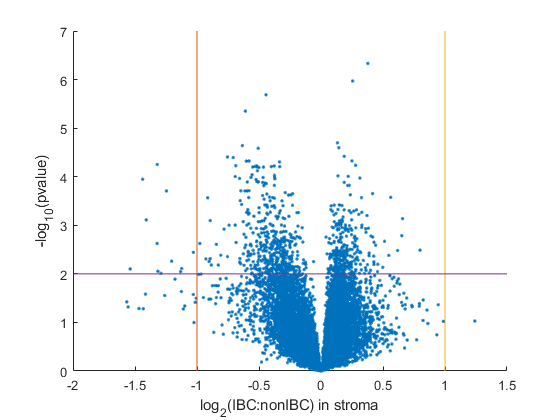

negfc = 2.^log2fc; 
%  convert the log2 fold change to the true value: 
% negfc=2^1=2 (log2fc =1), negfc=2^0=1(log2fc =0), negfc=2^(-1)= 0.5 (log2fc =-1).
negfc(negfc<1) = - 1./negfc(negfc<1); 
% convert all negfc<1, to a negtive number of - 1./negfc(negfc<1)
% negfc=2^(-1)= 0.5 (log2fc =-1), the new negfc =-1/0.5=-2
% which means Istroma_ibc is expressing less than Istroma_nonIBC
% negfc>1  means Istroma_ibc is expressing more Istroma_nonIBC
% Add the foldchange information to the dpvals object:
dpvals=[dpvals bioma.data.DataMatrix(negfc,'ColNames',{'negfc'})];

% Select the genes with pvalue<=0.01 and FC>=1.5.
I = dpvals(:,'p-values')<=0.01 & abs(dpvals(:,'negfc'))>=1.5;
dsigfc = dpvals(I,:);
dsigfc = dsigfc.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5. Showing top 5:\n',size(dsigfc,1));
disp(dsigfc(1:5,:))

Matlab has a mavolcanoplot() tool that helps you explore significantly different genes for different pvalue and fold change cutoffs.

figure;
mavolcanoplot(d.double(:,Istroma_ibc), d.double(:,Istroma_nonibc), dpvals.double(:,1),'Labels',d.rownames)

## Writing data into Excel File

Create a cell array containing the data that you want appear in an Excel sheet.

I=find(dpvals(:,1)<=0.01);
nsig=numel(I);
xlsdata = cell(nsig, 3); %each row will contain genesymbol,pvalue,negfc
for i=1:nsig

Error using bioma.data.DataMatrix/subsref (line 101)
Index exceeds DataMatrix dimensions.

	gene=dpvals.rownames{I(i)};
	p=dpvals.double(I(i), 1);
	nfc=dpvals.double(I(i), 2);
	xlsdata(i,:) = {gene p nfc};
end

xlsdata=[ {'genesymbol' 'pvalue' 'negfc'}; xlsdata]; %add the header row.

Error using uimenu
First argument must be a valid parent, such as a Figure or Panel object.
Error in mavolcanoplot>resetFigureTools (line 1006)
uimenu(hw,'Label','Export to Workspace...','Position',1, 'Callback', @exportDiffResults);
Error in mavolcanoplot (

xlswrite('stromaibc.xlsx',xlsdata,'siggenesIBC_nonIBC');



%-------------------------------------------------------------------------

## Data Analysis: Hierarchical Clustering (co-expressed)

Let's cluster genes and samples using hierarchical clustering. Clustering can be very time consuming, so let's only do it for a subset of the genes.

genevarfilter   [https://www.mathworks.com/help/bioinfo/ref/genevarfilter.html](https://www.mathworks.com/help/bioinfo/ref/genevarfilter.html)

clustergram  https://www.mathworks.com/help/bioinfo/ref/clustergram.html

% One idea is to only keep the genes that vary most across samples
% (ingoring sample groups.) This can be done using:
I=genevarfilter(d, 'Percentile',99); %remove 99% of genes
d2 = d( I, :);

% Another option is to keep the genes that vary across sample groups. Since
% we already did differential expression analysis above, let's use the genes
% resulting from it. (Note that we only compared IBC vs. nonIBC in stroma;
% one would really need to repeat differential expression analysis for
% other pairs of groups of samples, and use the union of all significant
% genes).
Isig=dpvals(:,'p-values')<=0.05; %let's use 0.05 threshold to remove some more genes.
d2 = d(Isig,:);
cg = clustergram(d2,'Standardize','Row');

## Data-Analysis: k-means clustering

k-means is another method to generate groups of genes.

kmeans [https://www.mathworks.com/help/stats/kmeans.html.](https://www.mathworks.com/help/stats/kmeans.html.) 

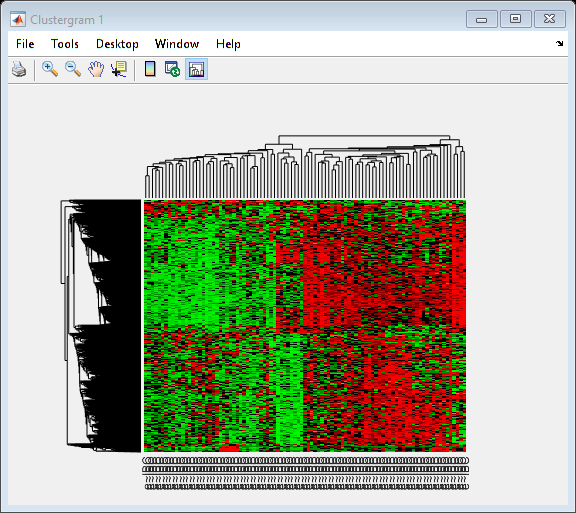

Iclust = kmeans(d2, 6, 'dist','corr'); % return a row vector of 1,2,3,4,5,6 which indicating which cluster
% a a patient belongs. 

% Once you have the Iclust membership values, you can again generate barplot
d2avgavg=zeros(6,4);
for i=1:6; for j=1:4
		d2avgavg(i,j) = mean(mean(d2(Iclust==i,Igroups==j)));
end; end

clf
bar(d2avgavg); legend(groupnames);
% legend(groupnames, 'Location','northeastoutside');

xlabel('gene clusters');



## Data Analysis: Principal Component Analysis (PCA)

Each gene is a multi-dimensional vector (as many dimensions as the number of samples). We often want to visualize genes in a lower (2D) space. Let's use PCA to reduce data dimensionality while preserving as much of the original information as possible. 

d2 data is reduced to 547X546 (95 principle components)  

pca() https://www.mathworks.com/help/stats/pca.html

`pc = pca(`[`X`](https://www.mathworks.com/help/stats/pca.html#bth9ibe-X)`)` returns the principal component coefficients, also known as loadings, for the *n*-by-*p* data matrix `X`. Rows of `X` correspond to observations and columns correspond to variables. The coefficient matrix is *p*-by-*p*. 

reduced: principal component reduced(scores) are the representations of `X` in the principal component space. Rows of reduced (`score)` correspond to observations, and columns correspond to components (principle 1 ....).

pcvars: the principal component variances

[pc, reduced, pcvars] = pca(d2); 
%pc (the coefficients, loadings or weights),  how the variables are combined
% reduced(:,1), reduced(:,2). the first two principle components

% reduced has as many columns as the original data. But the first column
% now contains the most information (PC1), the second column contains the second
% most (PC2), etc. Let's just use the first two columns to show genes on a
% figure.

figure;
scatter(reduced(:,1), reduced(:,2));

We can combine the clustering and PCA and show the genes in different clusters with a different color.

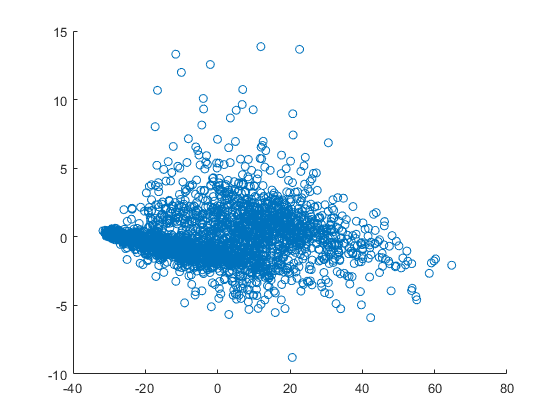

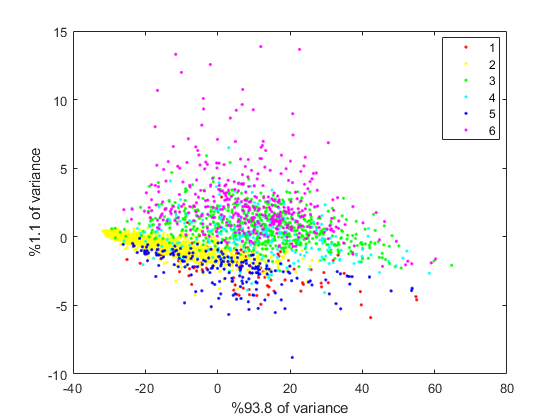

figure;
gscatter(reduced(:,1), reduced(:,2), Iclust);

% we can label the points using the text() function. Let's do that for the
% first 5 genes.
% for i=1:5; text(reduced(i,1),reduced(i,2), d2.rownames{i}, 'FontWeight','bold', 'FontSize',13); end

% Whenever you show results of PCA, you should report the amount of
% variance captured by the reduced data.
pcvars = pcvars / sum(pcvars);
xlabel(sprintf('%%%.1f of variance', pcvars(1)*100));
ylabel(sprintf('%%%.1f of variance', pcvars(2)*100));



%-------------------------------------------------------------------------